## **1 Definição variaveis **

clear all; % liberta a memória do computador
nbit = 20000; % comprimento da sequencia binaria, valor variável
R = 1e6; % taxa de transmissão em bit/s
N = 16; % nº de amostras por símbolo
fa = N*R; % frequência de amostragem
Ntempo = 32; % nº de símbolos a visualizar nos diagramas temporais
F=0.1, % fator de decaimento do cosseno elevado

F = 0.1000

## **2.1 Geração de sinal**

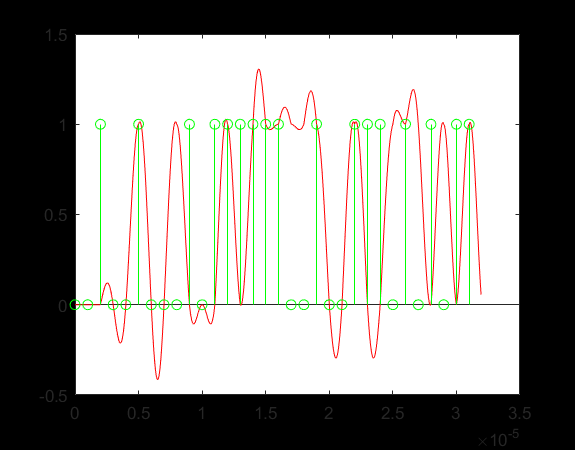

inf = randi([0 1],1,nbit); % seq. binaria com igual prob. para '0' e '1'
[s_tx,t] = rcosflt(inf,R,N*R,'fir/normal',F);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
title('Sequência com formatação coseno-elevado');
hold on;
x = 0:1/R:(Ntempo-1)/R;
stem(x,inf(1:Ntempo),'g');
hold off

## **2.2 Diagrama de Olho**

## **2.2.1 **

eyediagram(s_tx(1:256*N),2*N, 2);

## 2.2.2

%tempo de vida certo
%não há desvio em relação ao tempo de vida e tempo de amostragem ótimo 
%bem definido.NÍVEL DE DECISAO OTIMA ACIMA DE 0.5
%MARGEM DE RUIDO 0.5. Se o bit deo«mora 1ms quer dizer que temos 500ns d
%de jitter. Interferencia entre símbolos=0;

## 2.3 Densidade especral de potência

## 2.3.1

windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');

Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
%2.3.2
hold on
Hxx=densidade(f,R,F);
plot(f,10*log10(Hxx/1e-3),'b');

## 2.4 Impacto do fator de decaimento 

## Alterar para 50%

## 2.2.1

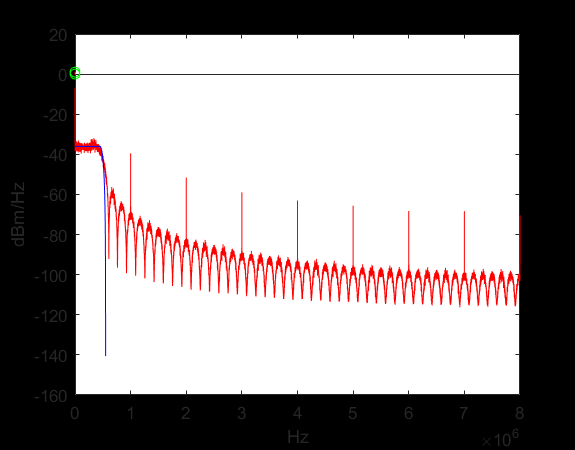

%alterar  F=0.5 
F5=0.5;
inf = randi([0 1],1,nbit); % seq. binaria com igual prob. para '0' e '1'
[s_tx,t] = rcosflt(inf,R,N*R,'fir/normal',F5);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
title('Sequência com formatação coseno-elevado');
hold on;
x = 0:1/R:(Ntempo-1)/R;
stem(x,inf(1:Ntempo),'g');
hold off

## 2.2.2

eyediagram(s_tx(1:256*N),2*N, 2);

## 2.2.3

windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');

Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
%2.3.2
hold on
Hxx5=densidade(f,R,F5);
plot(f,10*log10(Hxx5/1e-3),'b');

## Para 90%

## 2.2.1

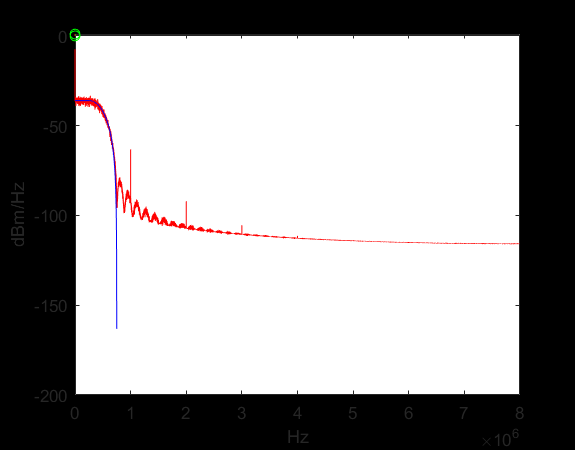

F9=0.9;

inf = randi([0 1],1,nbit); % seq. binaria com igual prob. para '0' e '1'
[s_tx,t] = rcosflt(inf,R,N*R,'fir/normal',F9);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
title('Sequência com formatação coseno-elevado');
hold on;
x = 0:1/R:(Ntempo-1)/R;
stem(x,inf(1:Ntempo),'g');
hold off

## 2.2.2

eyediagram(s_tx(1:256*N),2*N, 2);

## 2.2.3

windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');

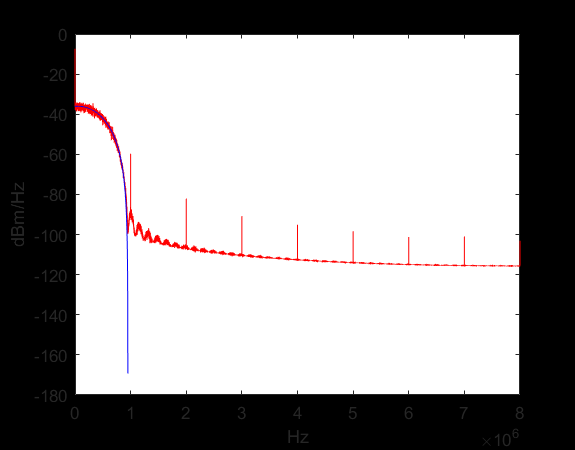

Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
%2.3.2
hold on
Hxx9=densidade(f,R,F9);
plot(f,10*log10(Hxx9/1e-3),'b');

## 2.5 Impacto do canal

## 2.5.1 